# ECE310 Project 5 - Ayden Shankman

clc; clear; close all;

load pj2data.mat

## Problem A.1

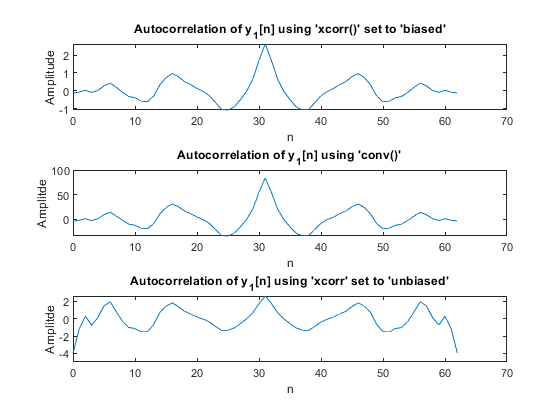

y1 = y(1:32);
n = [0:62];

cyy1 = xcorr(y1, y1, 'biased');
cyy1_unbiased = xcorr(y1, y1, 'unbiased');

cyy2 = conv(y1, flip(y1));

figure;
subplot(3, 1, 1);
plot(n, cyy1);
title("Autocorrelation of y_1[n] using 'xcorr()' set to 'biased'");
xlabel("n");
ylabel("Amplitude");

subplot(3, 1, 2);
plot(n, cyy2);
title("Autocorrelation of y_1[n] using 'conv()'");
xlabel("n");
ylabel("Amplitde");

subplot(3, 1, 3);
plot(n, cyy1_unbiased);
title("Autocorrelation of y_1[n] using 'xcorr' set to 'unbiased'");
xlabel("n");
ylabel("Amplitde");

% When xcorr is set to 'unbiased' it calculates the unbiased estimate of the cross-correlation

## Problem A.2

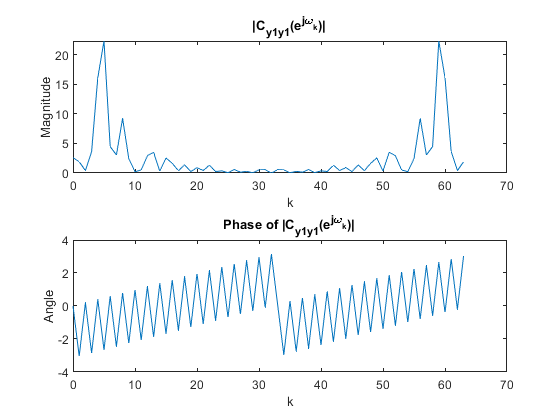

% The Fourier Transform of the autocorrelation function is equal to the
% power density spectrum which is a postive real function

cyy1_DFT = fft(cyy1, 64);
k = [0:63];


figure;
subplot(2, 1, 1);
plot(k, abs(cyy1_DFT));
title("|C_{y1y1}(e^{j\omega_k})|");
xlabel("k");
ylabel("Magnitude");

subplot(2, 1, 2);
plot(k, angle(cyy1_DFT));
title("Phase of |C_{y1y1}(e^{j\omega_k})|");
xlabel("k");
ylabel("Angle");

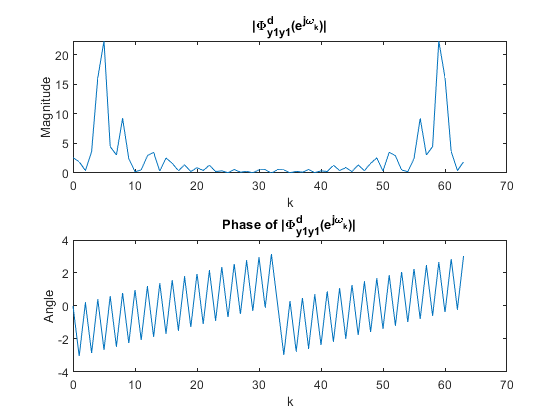


phi_y1y1 = cyy2/32;
phi_y1y1_DFT = fft(phi_y1y1, 64);

figure;
subplot(2, 1, 1);
plot(k, abs(phi_y1y1_DFT));
title("|\Phi^d_{y1y1}(e^{j\omega_k})|");
xlabel("k");
ylabel("Magnitude");

subplot(2, 1, 2);
plot(k, angle(phi_y1y1_DFT));
title("Phase of |\Phi^d_{y1y1}(e^{j\omega_k})|");
xlabel("k");
ylabel("Angle");


% The 64 point DFT of phi_y1y1 is the same as the 64 point DFT of cy1y1

## Problem A.3

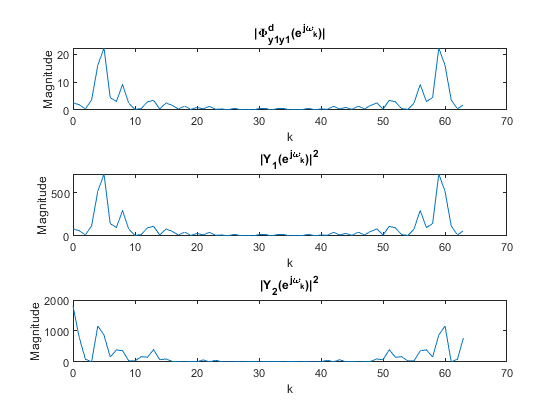

Y1 = abs(fft(y1, 64).^2);
Y2 = abs(fft(y(1:64), 64)).^2;

figure;
subplot(3, 1, 1);
plot(k, abs(phi_y1y1_DFT));
title("|\Phi^d_{y1y1}(e^{j\omega_k})|");
xlabel("k");
ylabel("Magnitude");

subplot(3, 1, 2);
plot(k, Y1);
title("|Y_1(e^{j\omega_k})|^2");
xlabel("k");
ylabel("Magnitude");

subplot(3, 1, 3);
plot(k, Y2);
title("|Y_2(e^{j\omega_k})|^2");
xlabel("k");
ylabel("Magnitude");


% They are all similar but are scaled differently

## Problem B.1

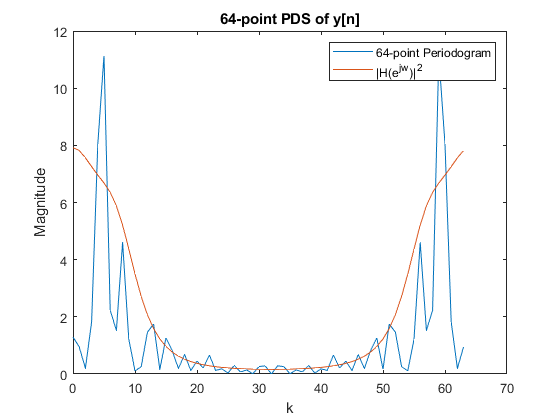

periodgram_y = Y1/64;
des_freq = downsample(Hejw2, 512/64);

figure;
plot(k, periodgram_y, k, des_freq);
legend('64-point Periodogram','|H(e^{jw})|^2' );
title('64-point PDS of y[n]'); 
xlabel('k');
ylabel('Magnitude');


err1 = sum(abs((periodgram_y - des_freq)).^2)/64;
disp("Estimation error using only first 32-points of data: " + err1);

Estimation error using only first 32-points of data: 7.5039


## Problem B.2

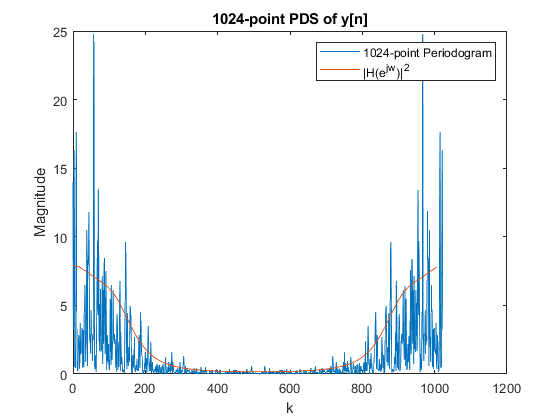

periodgram_y1024 = abs(fft(y, 1024)).^2/1024;

figure;
plot(0:1023, periodgram_y1024, k*1024/64, des_freq);
legend('1024-point Periodogram','|H(e^{jw})|^2');
title('1024-point PDS of y[n]'); 
xlabel('k');
ylabel('Magnitude');


err2 = sum(abs((downsample(periodgram_y1024,floor(1024/64))-des_freq)).^2)/64;
disp("Estimation error using all 512-points of data: " + err2);

Estimation error using all 512-points of data: 5.9197


## Problem B.3

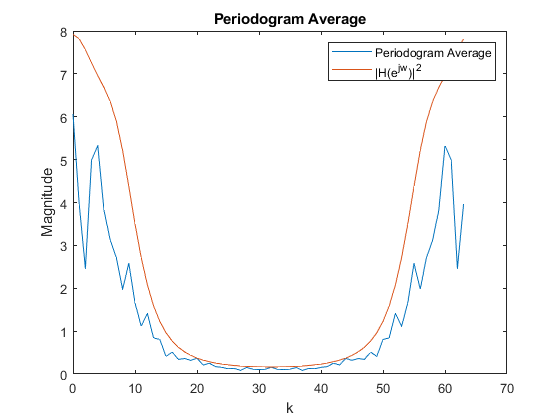

windows = reshape(y, [32 16]);
periodograms = abs(fft(windows,64)).^2/64;
p_avg = sum(periodograms,2)/16;

figure;
plot(k, p_avg, k, des_freq);
title('Periodogram Average');
legend('Periodogram Average','|H(e^{jw})|^2');
xlabel('k');
ylabel('Magnitude');


err3 = sum(abs(p_avg'-des_freq).^2)/64;
disp("Estimation error using periodogram averaging: " + err3);

Estimation error using periodogram averaging: 3.1403



% The periodograms average is less than the desired frequency response
% unlike the first 2. Also, the estimation error for this one is the
% smallest out of the 3.

## Problem B.4

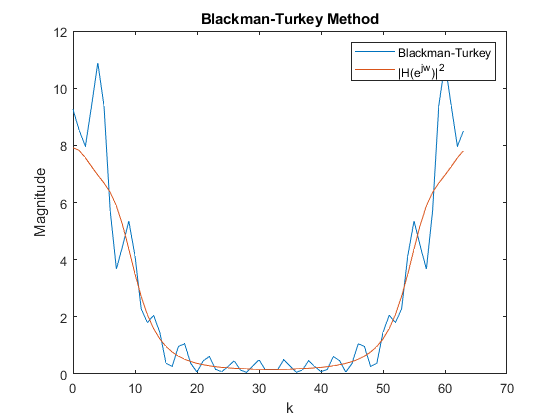

phi_yy = xcorr(y,y,'unbiased');
phi_yy = phi_yy(497:527);
phi_yy_DFT = abs(fft(phi_yy, 64));

figure;
plot(k, phi_yy_DFT, k, des_freq);
title('Blackman-Turkey Method');
legend('Blackman-Turkey','|H(e^{jw})|^2');
xlabel('k');
ylabel('Magnitude');


err4 = sum(abs(phi_yy_DFT-des_freq).^2)/64;
disp("Estimation error using Blackman-Turkey method: " + err4);

Estimation error using Blackman-Turkey method: 1.1899


## Probelm B.5

PDS = [1:4]';
Error = [err1, err2, err3, err4]';
T = table(PDS, Error);
T(1:4,:)

ans = 4×2 table
    PDS    Error 
    ___    ______

     1     7.5039
     2     5.9197
     3     3.1403
     4     1.1899


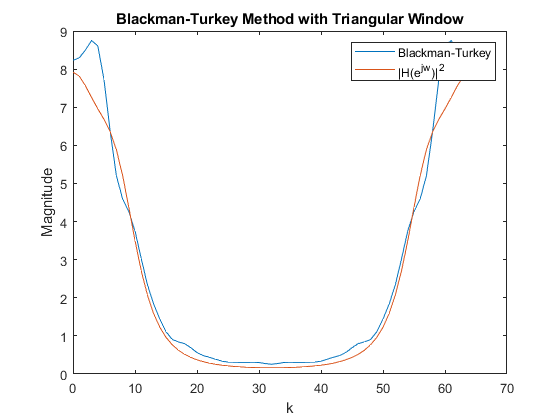


% Indirect Blackman-Tukey performed the best.

% Instead of taking the average of different waveforms, the Blackman-Tukey method uses the autocorrelation
% function which smoothes the wave by using a window.

phiyy = phi_yy.*triang(31)';
phi_yy_DFT = abs(fft(phiyy, 64));

figure;
plot(k, phi_yy_DFT, k, des_freq);
title('Blackman-Turkey Method with Triangular Window');
legend('Blackman-Turkey ','|H(e^{jw})|^2');
xlabel('k');
ylabel('Magnitude');


err5 = sum(abs(phi_yy_DFT-des_freq).^2)/64;
disp("Estimation error using Blackman-Turkey method and Triangular Window: " + err5);

Estimation error using Blackman-Turkey method and Triangular Window: 0.27679



% The performance using a traingular window is better than using a 
% rectangular window. In B.4 it is truncating the autocorrelation
% which causes the largest variances to be cut off and compromises the resolution. 